%% Magnitude and Phase
clc; clear all;
s = tf('s')

n = 2500;
d = s*(s+6)*(s+50);
g = n/d; %<--------fill in the
figure(1)
margin(g)



%% Laplace and Inverse Laplace
clc; clear all;
syms s t
a = (s)/((s+2)^2+16)
F = laplace(a,t,s)
f = ilaplace(F,s,t)


$$\$$



%% residue
clc; clear all;

n = [1];
d = [1 1 4];
n1= [1 0];


d1= [1 10];
t = tf(n,d);
t1= tf(n1,d1);
a = t/(1+t*t1);

%[r,p,k] = residue(a)




%% TIME CONSTANT   SETTLING TIME
clc; clear all;
s = tf('s');
k = 1;
G = 1/s*20/(s+20)
[z,p,k] = zpkdata(G)
G1 = zpk(z,p,k,'DisplayFormat', 'timeconstant')
damp(G)
[w, zeta, p] = damp(G)
tau = 1./w


%%

clc; clear all;
syms s t
G = 1/s * 5/(s+5);
a = ilaplace(G)

$$a = 1-{\mathrm{e}}^{-5\,t}$$

b = laplacian(G)

$$b = \frac{10}{s\,{\left(s+5\right)}^{3}}+\frac{10}{s^{2}\,{\left(s+5\right)}^{2}}+\frac{10}{s^{3}\,\left(s+5\right)}$$

v = laplace(a)

$$v = \frac{1}{s}-\frac{1}{s+5}$$

## HW 3: PROBLEM  4								

Find the **capacitor voltage **in the network shown in Figure P4.2 if the switch closes at *t=*� 0. Assume **zero initial conditions**. Also find the **time constant, rise time, and settling time** for the capacitor voltage. [Sections: 4.2, 4.3] 						

	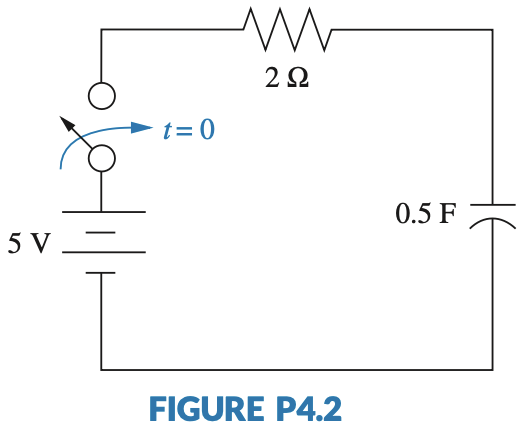			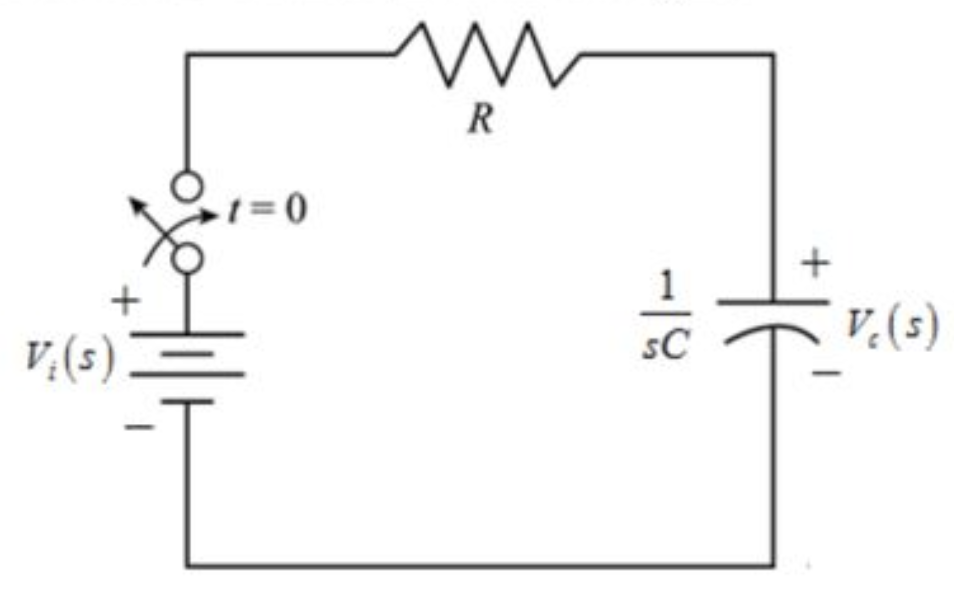

Applying voltage division for R and C: 


$$\frac{V_c \left(s\right)}{V_i \left(s\right)}=\frac{\frac{1}{\textrm{RC}}}{s+\frac{1}{\textrm{RC}}}=\frac{1}{s+1}$$
	 

where  $V_c \left(s\right)=\frac{5}{s\;}\left(\frac{1}{s+1}\right)=\frac{5}{s}-\frac{5}{s+1}$

**Capacitive voltage**

clc; clear all;
syms s t
C = .5;
R = 2;
% Voltage division equation for R and C 
V_c= simplify(1/(s*C)/(1/(s*C)+R))

$$V\_c = \frac{1}{s+1}$$

G = 5/s * V_c

$$G = \frac{5}{s\,\left(s+1\right)}$$

% Partial fraction expansion
P = partfrac(G)

$$P = \frac{5}{s}-\frac{5}{s+1}$$

iL= ilaplace(G)

$$iL = 5-5\,{\mathrm{e}}^{-t}$$

v = laplace(iL,s)

$$v = \frac{5}{s}-\frac{5}{s+1}$$

**Time Constant**

T = 1/(R*C)

T = 1

**Rise time**

T_r = 2.2/(R*C)

T_r = 2.2000

**Settle time**

T_s = 4/(R*C)

T_s = 4

## HW 3: Problem 8

For each of the transfer functions shown below, find the locations of the **poles and zeros**, **plot** them on the *s*-plane, and then write an expression for the **general form **of the step response without solving for the inverse Laplace transform. State the nature of each response (overdamped, underdamped, and so on). [Sections: 4.3, 4.4] 

## a. $\frac{2}{s+2}\to A+{\textrm{Be}}^{-2t} \to 1-e^{-2t}$

clc; clear all;
s = tf('s');
T = tf([2],[1 2])

T =
 
    2
  -----
  s + 2
 
Continuous-time transfer function.



[z,p,k] = zpkdata(T)

z = 1×1 cell array
    {0×1 double}


p = 1×1 cell array
    {[-2]}


k = 2

Stability = isstable(T)% 1 = stable, 0 = unstable

Stability = logical
   1


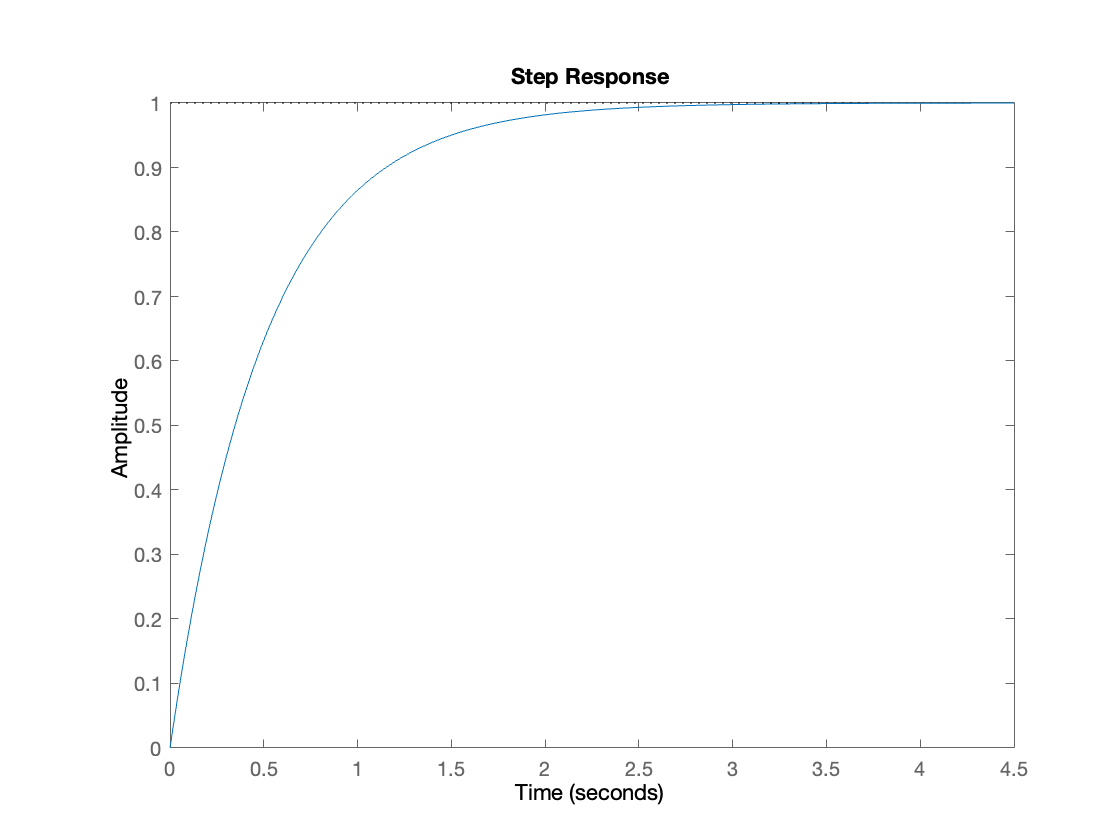

step(T)

## b. $T\left(s\right)=\frac{5}{\left(s+3\right)\left(s+6\right)}\to A+{\textrm{Be}}^{-3t} +{\textrm{Ce}}^{-6t} \to \frac{5}{18}-\frac{5}{9}e^{-3t} +\frac{5}{18}e^{-6t}$

clc; clear all; 
syms s
n = 5; 
d = s*(s+3)*(s+6);
D = expand(d)

$$D = s^{3}+9\,s^{2}+18\,s$$

f = factor(D)

$$f = \left(\begin{array}{ccc} s & s+6 & s+3 \end{array}\right)$$

T_s = n/d

$$T\_s = \frac{5}{s\,\left(s+3\right)\,\left(s+6\right)}$$

iL = ilaplace(T_s)

$$iL = \frac{5\,{\mathrm{e}}^{-6\,t}}{18}-\frac{5\,{\mathrm{e}}^{-3\,t}}{9}+\frac{5}{18}$$

F = factor(d)

$$F = \left(\begin{array}{ccc} s & s+3 & s+6 \end{array}\right)$$

a = [n]

a = 5

b = sym2poly(D)

b =      1     9    18     0



T = tf(a,b)

T =
 
          5
  ------------------
  s^3 + 9 s^2 + 18 s
 
Continuous-time transfer function.



[z,p,k]= zpkdata(T)

z = 1×1 cell array
    {0×1 double}


p = 1×1 cell array
    {3×1 double}


k = 5

## STABILITY

B = isstable(T)

B = logical
   0


## DAMPING

Damping of 1 is overdamped

damp(T)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -3.00e+00     1.00e+00       3.00e+00         3.33e-01    
 -6.00e+00     1.00e+00       6.00e+00         1.67e-01    


## POLES AND ZEROS

[r,p,k] = residue(a,b)

r =     0.2778
   -0.5556
    0.2778


p =     -6
    -3
     0



k =

     []



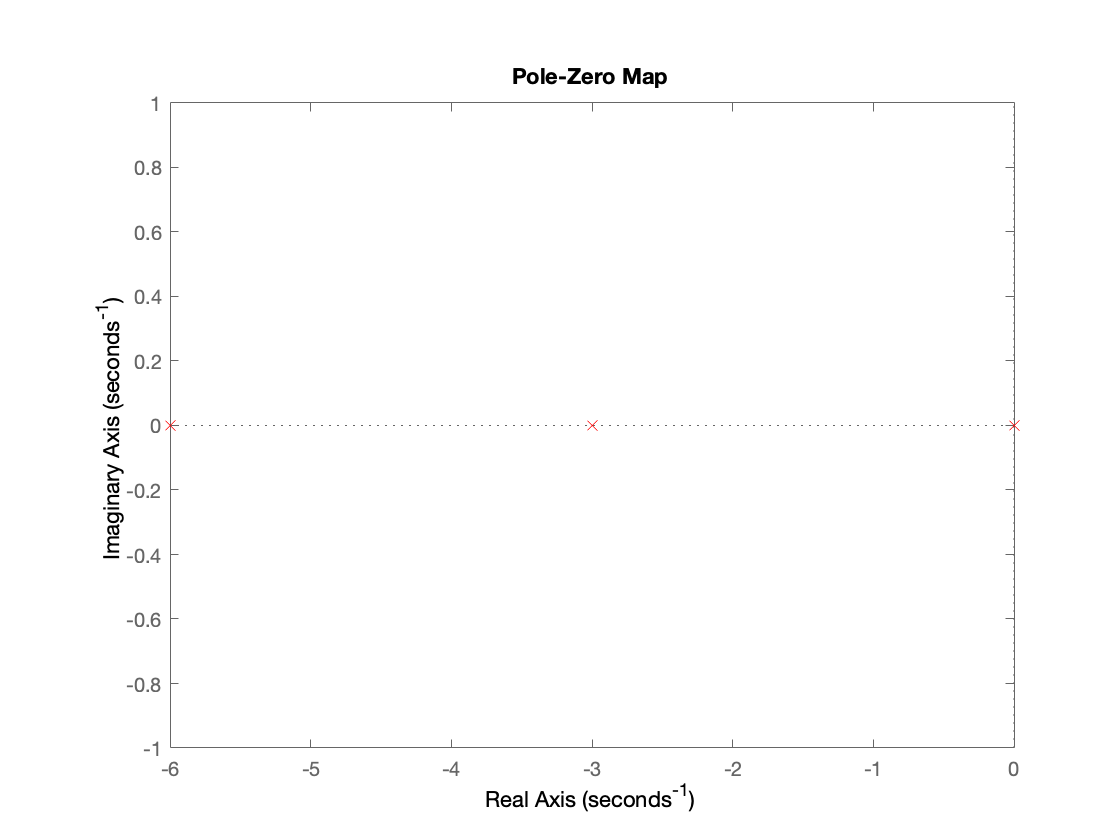

pzplot(T,'r')

Stable since poles oar all negative and on the

## d. $T\left(s\right)=\frac{20}{s^2 +6s+144}\to \;$

n = 20;
d = s^2+6*s+144;
D = expand(d)

$$D = s^{2}+6\,s+144$$

f = factor(D)

$$f = s^{2}+6\,s+144$$

T_s = n/d

$$T\_s = \frac{20}{s^{2}+6\,s+144}$$


a = [n]

a = 20

b = sym2poly(D)

b =      1     6   144



T = tf(a,b,.1)

T =
 
        20
  ---------------
  z^2 + 6 z + 144
 
Sample time: 0.1 seconds
Discrete-time transfer function.





[z,p,k]= zpkdata(T)

z = 1×1 cell array
    {0×1 double}


p = 1×1 cell array
    {2×1 double}


k = 20

B = isstable(T)

B = logical
   0


### DAMPING: 

Damping of -8 is **under damped**

damp(T)

                                                                                    
         Pole             Magnitude     Damping       Frequency      Time Constant  
                                                    (rad/seconds)      (seconds)    
                                                                                    
 -3.00e+00 + 1.16e+01i     1.20e+01    -8.06e-01       3.08e+01        -4.02e-02    
 -3.00e+00 - 1.16e+01i     1.20e+01    -8.06e-01       3.08e+01        -4.02e-02    


### Poles and Zero's:

[r,p,k] = residue(a,b)

r =    0.0000 - 0.8607i
   0.0000 + 0.8607i


p =   -3.0000 +11.6190i
  -3.0000 -11.6190i



k =

     []



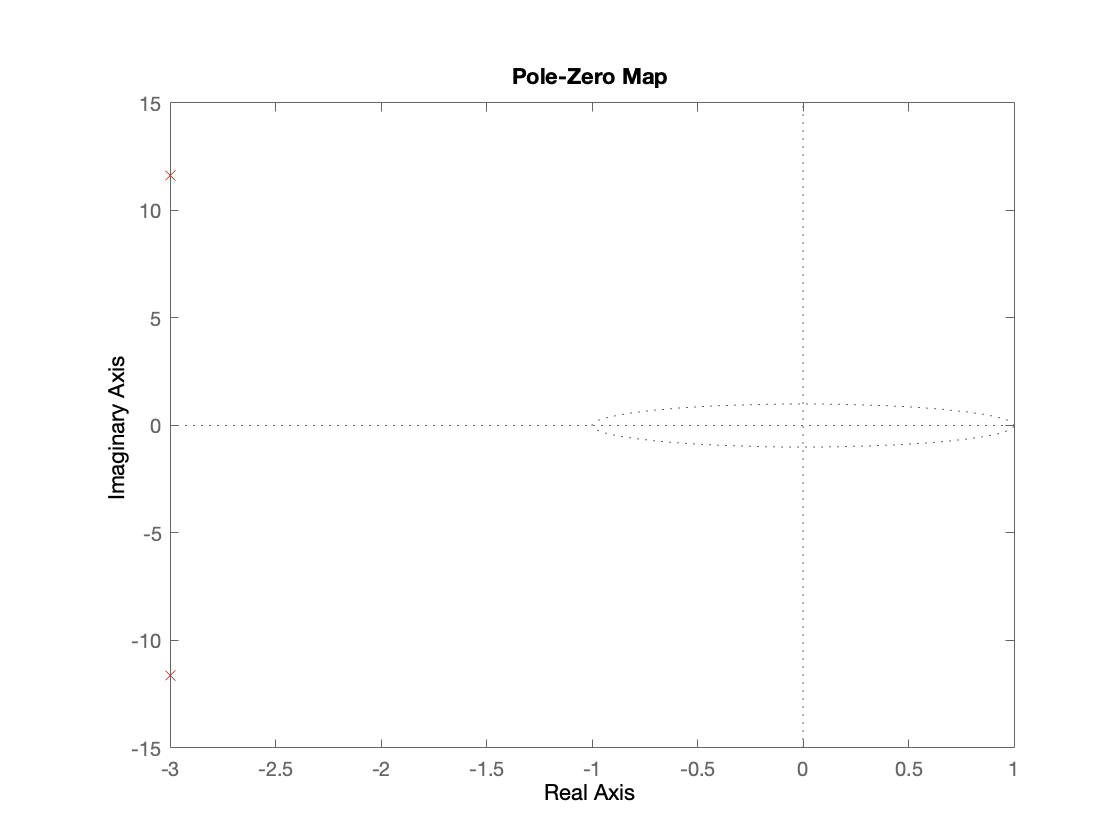

pzmap(T, '^r')

# **TRANSIENT ANAYSIS**

## f. $T\left(s\right)=\frac{\left(s+5\right)}{{\left(s+10\right)}^2 }$

clc; clear all; 
syms s

n =  s-2; 
d =  s*(s+1)*(s+2)^2;
D = expand(d)

$$D = s^{4}+5\,s^{3}+8\,s^{2}+4\,s$$

q = solve(D)

$$q = \left(\begin{array}{c} -2\\ -2\\ -1\\ 0 \end{array}\right)$$

T_s = n/d

$$T\_s = \frac{s-2}{s\,\left(s+1\right)\,{\left(s+2\right)}^{2}}$$

iL = ilaplace(T_s)

$$iL = 3\,{\mathrm{e}}^{-t}-\frac{5\,{\mathrm{e}}^{-2\,t}}{2}-2\,t\,{\mathrm{e}}^{-2\,t}-\frac{1}{2}$$


%try
    a = sym2poly(n)

a =      1    -2


    
%catch ME
%    a = [n]
%end
b = sym2poly(D)

b =      1     5     8     4     0



f = factor(D)

$$f = \left(\begin{array}{cccc} s & s+1 & s+2 & s+2 \end{array}\right)$$

    

T = tf(a,b)

T =
 
            s - 2
  -------------------------
  s^4 + 5 s^3 + 8 s^2 + 4 s
 
Continuous-time transfer function.



[z,p,k]= zpkdata(T) %Cr 

z = 1×1 cell array
    {[2]}


p = 1×1 cell array
    {4×1 double}


k = 1

## STABILITY

B = isstable(T) %1 = stable

B = logical
   0


## DAMPING

Damping of 1 is overdamped

damp(T)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.00e+00     1.00e+00       1.00e+00         1.00e+00    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    


## POLES AND ZEROS

[r,p,k] = residue(a,b)

r =    -2.5000
   -2.0000
    3.0000
   -0.5000


p =    -2.0000
   -2.0000
   -1.0000
         0



k =

     []



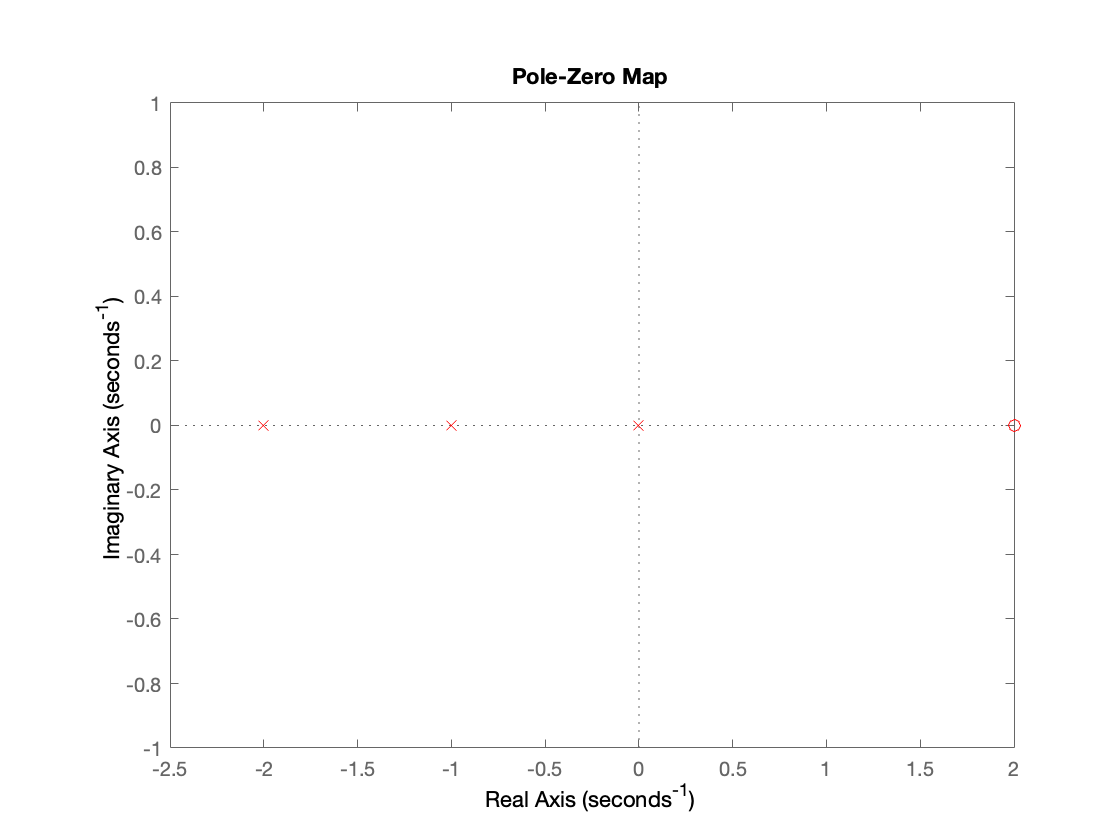

pzplot(T,'r') 

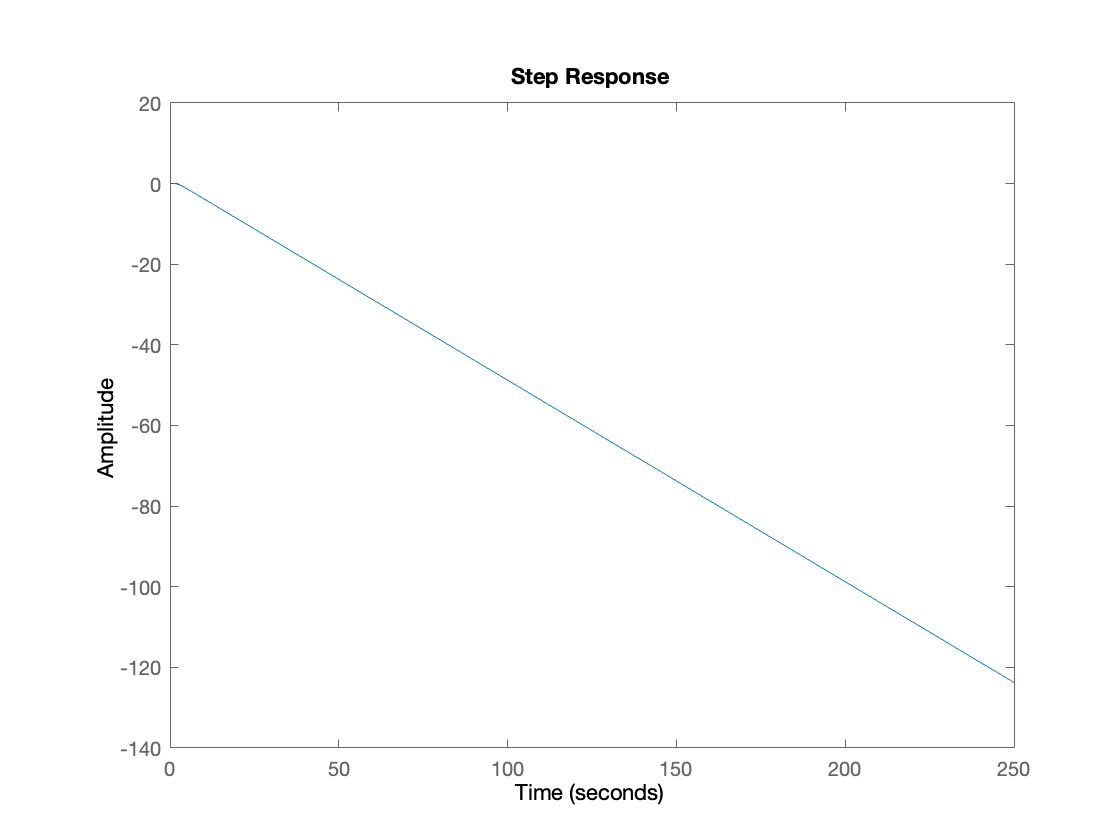

step(T)

stepinfo(T)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


Stability comparison

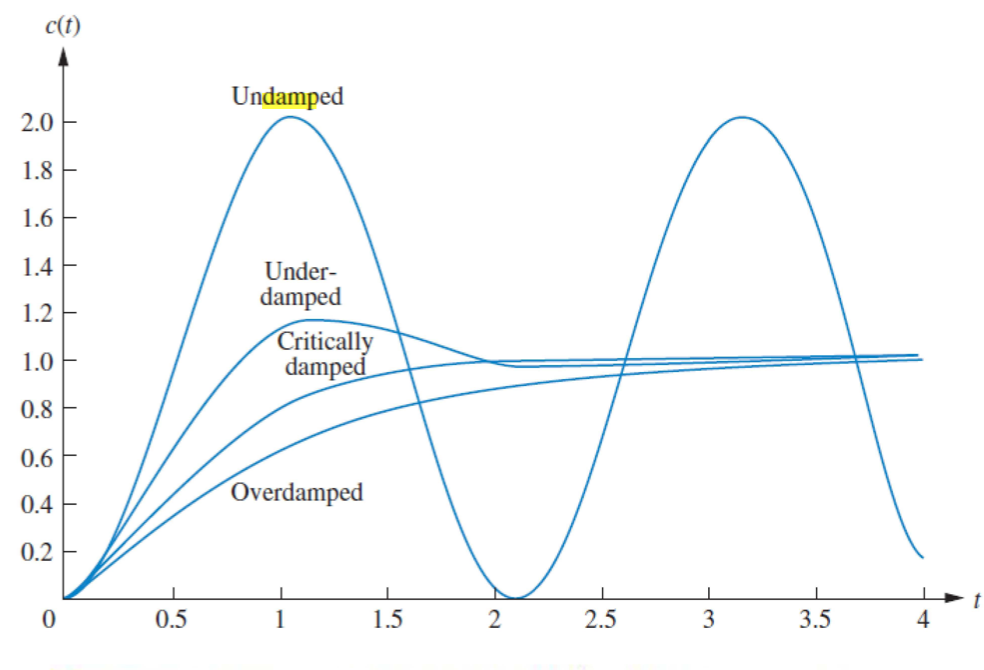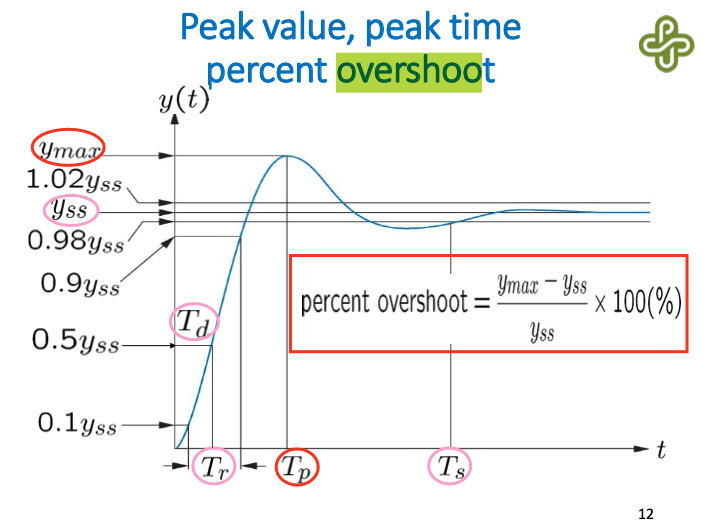

### PERCENT OVERSHOOT %OS

Y_max = .0833; % SettlingMin

Y_min = 1.3896e-6; % SettlingMax

OS = (Y_max-Y_min)/(Y_min)*100

OS = 5.9944e+06

### damping ratio &

b 

b =      1     5     8     4     0


w = sqrt( b(3))  %[NA dp w]

w = 2.8284

dp= (b(2))/(w*2)

dp = 0.8839

Settle time

G = c/(s-1);
H = 1/2;
N = G*H/(1+G*H)

$$N = \frac{c}{2\,\left(\frac{c}{2\,\left(s-1\right)}+1\right)\,\left(s-1\right)}$$

simplifyFraction(N)

$$ans = \frac{c}{c+2\,s-2}$$